# Datasets y visualización

## Importar con readtable y readmatrix

%readmatrix
area_mm=readmatrix("../../Utils4SP/Datasets/areaMM.txt",'Delimiter','   ');

%readtable
PSD_bands=readtable("../../Utils4SP/Datasets/2021.10.04_IntensidadBobinas.xlsx");


## Funcion custom de Import File

%Pasa sonda Cassini
%Cassini=importfile_cassini("../../Utils4SP/Datasets/05358_mrdcd_sdfgmc_krtp_1s.asc",88,200);
Cassini=importfile_cassini("../../Utils4SP/Datasets/05358_mrdcd_sdfgmc_krtp_1s.asc",88,3000);

## Importar audio

[buho,fs_buho]=audioread("../../Utils4SP/Datasets/Owl.wav");
%Escuchar
%sound(buho,fs_buho)


## Datastore

% %Le indicamos que una carpeta es un datastore
% ds=datastore("../../Utils4SP/Datasets/AtmosferaLogger_V2/");
% ds.VariableNames=["Fecha" "Hora" "Pres_kpa" "Temp_C" "Hum_perc" "Bat_V"];
% ds.TextscanFormats=["%s" "%s" "%f" "%f" "%f" "%f"];
% 
% % ds.Delimiter="";
% % ds.VariableNames=["FechaHora" "Pres_kpa" "Temp_C" "Hum_perc" "Bat_V"];
% % ds.TextscanFormats=["%s" "%f" "%f" "%f" "%f"];
% 
% %Leer todas las entradas
% atmosfera_part=readall(ds);


## Primeras lecturas atmosfericas

ds=datastore("../../Utils4SP/Datasets/AtmosferaLogger");
ds.VariableNames=["Fecha" "Hora" "Pres_kpa" "Temp_C" "Hum_perc"];
ds.TextscanFormats=["%s" "%s" "%f" "%f" "%f"];
atmosfera=readall(ds);

## Reordenando

%Sólo si importa fecha y hora en dos columnas
atmosfera.DateTime=string(atmosfera.Fecha)+" "+string(atmosfera.Hora);
%Pasar de texto a fecha-hora
atmosfera.DateTime=datetime(atmosfera.DateTime,'Format',"yyyyMMdd HH:mm:ss");
%Parche por si la tabla ya se importó
%atmosfera_part.Properties.VariableNames=["Fecha" "Hora" "Pres_kpa" "Temp_C" "Hum_perc" "Bat_V"];


## Limpieza

Tomaremos los datos entre el 18-May y el 26 de mayo a las 6am

%Puntos inicial y final en el tiempo 
T1=datetime(2021,5,18,6,0,0)

T1 = datetime
   210518 06:00:00


T2=datetime(2021,5,26,6,0,0)

T2 = datetime
   210526 06:00:00



%Creando criterios de selección de datos
index= atmosfera.DateTime>T1 &...
    atmosfera.DateTime<T2;

atmosfera_part=atmosfera(index,:);




## Ploteo exploratorio

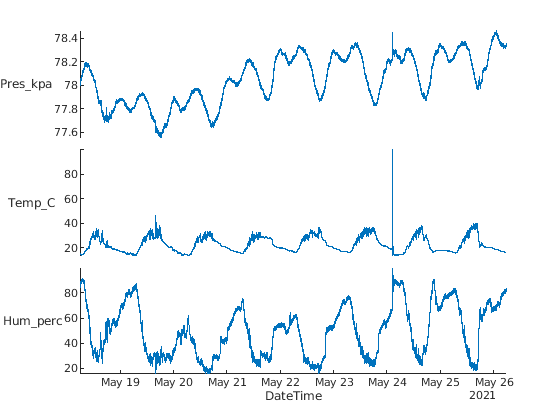

figure
stackedplot(atmosfera_part,'XVariable','DateTime')

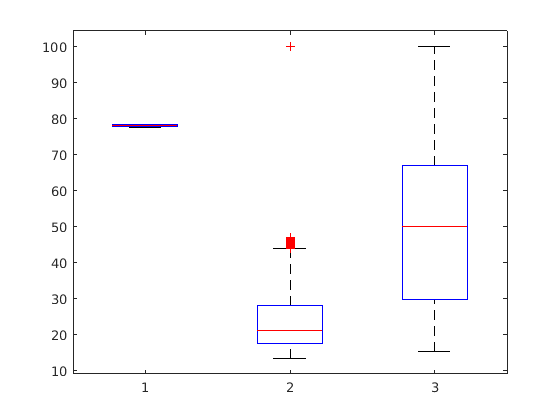


figure
boxplot(atmosfera_part{:,["Pres_kpa" "Temp_C" "Hum_perc"]})

## Histograma

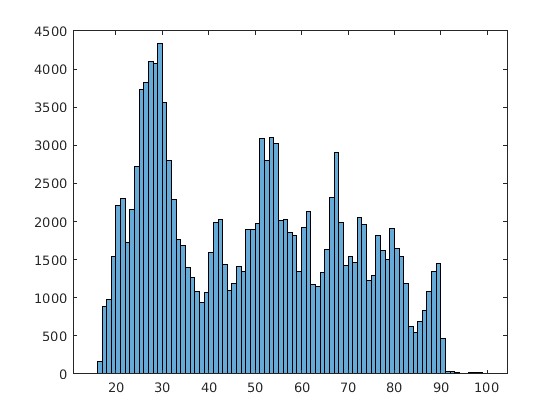

figure
histogram(atmosfera_part.Hum_perc)


figure
histogram(atmosfera_part.Hum_perc,'BinWidth',1)

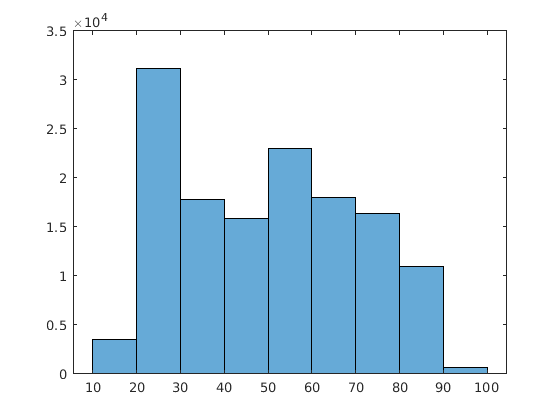


figure
histogram(atmosfera_part.Hum_perc,'BinWidth',10)

## Dispersión

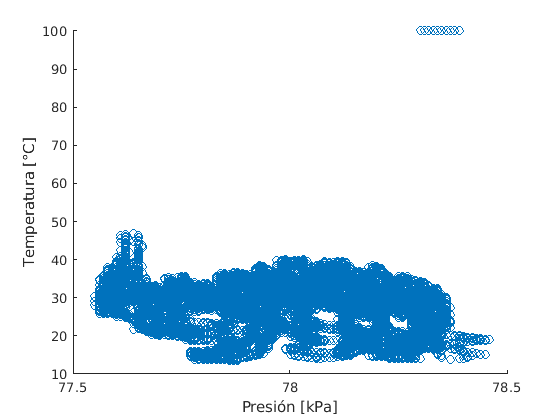

figure
scatter(atmosfera_part.Pres_kpa,atmosfera_part.Temp_C)
xlabel("Presión [kPa]")
ylabel("Temperatura [°C]")

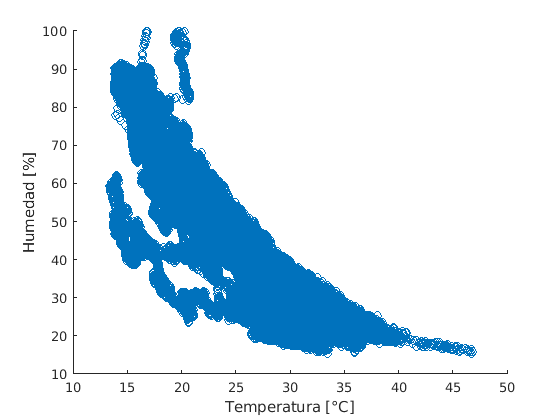


figure
scatter(atmosfera_part.Temp_C,atmosfera_part.Hum_perc)
xlabel("Temperatura [°C]")
ylabel("Humedad [%]")

## Plot matrix

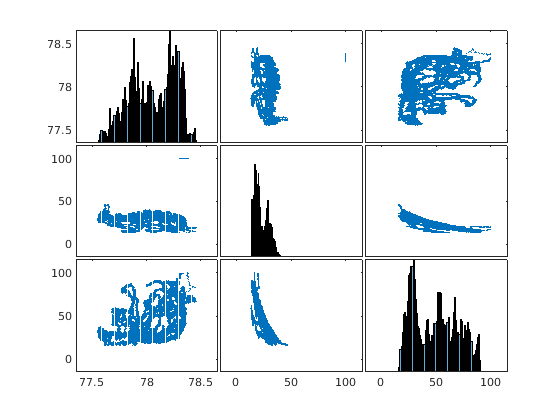

figure
plotmatrix(atmosfera_part{:,["Pres_kpa" "Temp_C" "Hum_perc"]})

## Tiledlayout

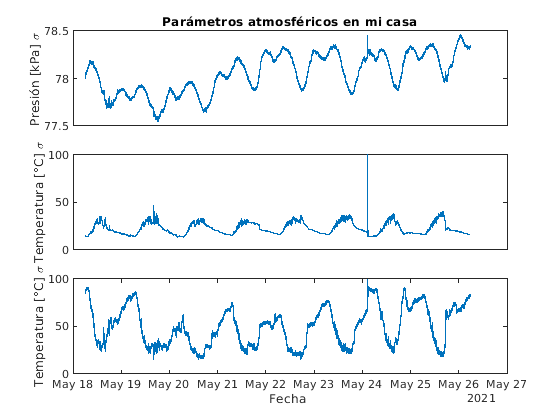

%tiledlayout("flow")
tiledlayout(3,1)
nexttile
plot(atmosfera_part.DateTime,atmosfera_part.Pres_kpa)
ylabel("Presión [kPa] \sigma")
%xlabel("Fecha ")
title("Parámetros atmosféricos en mi casa")
set(gca,'xtick',[])

nexttile
plot(atmosfera_part.DateTime,atmosfera_part.Temp_C)
ylabel("Temperatura [°C] \sigma")
%xlabel("Fecha ")
set(gca,'xtick',[])

nexttile
plot(atmosfera_part.DateTime,atmosfera_part.Hum_perc)
ylabel("Temperatura [°C] \sigma")
xlabel("Fecha ")

## Limpieza